# 034IN - FONDAMENTI DI AUTOMATICA - FUNDAMENTALS OF AUTOMATIC CONTROL - A.Y. 2023-2024

# Full Examination - June 21 2024

# PART 2 - Design of a Controller 

## Description of the Feedback Control System

Consider the feedback control system described by the block-scheme shown in the following figure

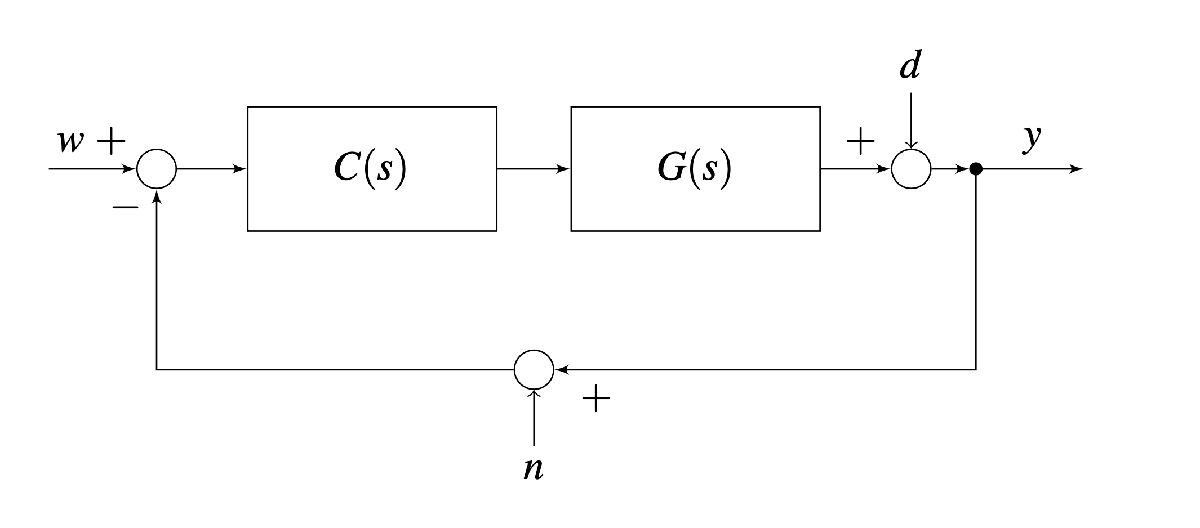	

where $G(s)$ is given by                


$$G(s) = \frac{4.815 \, (1+20\,s)}{(1+0.125\,s)^2}$$


## **Question**		

**Q1**: Design a controller $C(s)$ such that all following requirements are simultaneously met: 

- $\left\vert e(\infty) \right\vert = 0$ for $w(t) = \mathbf{1}(t)$, where $\mathbf{1}(t)$ denotes the unit step function; 

- For $d(t)=D \sin(\omega t) \cdot \mathbf{1}(t)$, $\forall D \in \mathbb{R}, \; D>0$, $\omega \in \left[0.1\,,\; 1.0\right]\;\text{rad/s}$, the corresponding steady-state output $y_{d,\,\infty}(t)$ generated by the disturbance $d(t)$, with $w(t)=0$, $n(t)=0$, $\forall t$ has magnitude satisfying $|y_{d,\,\infty}(t)| \le D/20$;

- For $n(t) = N \sin(\omega t) \cdot \mathbf{1}(t)$, $\forall N \in \mathbb{R},\;N>0$, $\omega \in \left[600,\,1200\right]\;\text{rad/s}$, the corresponding steady-state output $y_{n,\,\infty}(t)$ generated by the disturbance $n(t)$, with $w(t)=0$, $d(t)=0$, $\forall t$ has magnitude satisfying $|y_{n,\,\infty}(t)| \le N/25$.

- The phase margin satisfies $\varphi_m \ge 40^{\degree}$.			

## Solution 

Explain your design procedure and insert your code here.

% Insert your code
clear

addpath(genpath('BodeDiagram/'))

% let's define the transfer function builder element
s=tf('s');

Gs = 4.815*(1+20*s)/(1+0.125*s)^2; 

consideriamo il controllore $\;C_1 =\frac{\mu_C }{s}$ per soddisfare $\left\vert e(\infty) \right\vert = 0$ for $w(t) = \mathbf{1}(t)$. Infatti aggiungendo un polo nell'origine saremo certi che l'errore statico per w(t)=1(t) sarà nullo. Per ora inizializzo muC=1 e poi lo modificherò se servirà in seguito

muC = 1;
Cs = muC/s;

Ls = Cs * Gs


Ls =
 
        96.3 s + 4.815
  --------------------------
  0.01562 s^3 + 0.25 s^2 + s
 
Continuous-time transfer function.


Ora i punti 2 e 3 possono essere interpretati come vincoli su $|L\left(j\bar{\omega} \right)|$, infatti i 2 requisiti si possono tradurre nelle seguenti specifiche:


$$\left\vert L(j\,\bar \omega)\right\vert \ge 20,\; \forall \bar \omega \in \left[ \frac{1}{10},\;1\right]\longmapsto|L(j\bar\omega)|\geq26dB,\; \forall \bar \omega \in \left[ \frac{1}{10},\;1\right]$$
 


$$\left\vert L(j\,\bar \omega)\right\vert \le \frac{1}{25},\; \forall \bar \omega \in \left[ 600,\; 1200\right]\longmapsto\left\vert L(j\,\bar \omega)\right\vert \leq -28dB,\; \forall \bar \omega \in \left[ 600,\; 1200\right]$$


Ora con il control system design andiamo modificare il controllore in modo da rispettare tutte le condizioni

controlSystemDesigner(Gs, Cs)

Noto che anche modificando muC lasciando il sistema così com'è non riesco ad avere contemporaneamente sia i requisiti 1,2,3 rispettati e sia il margine di fase abbastanza alto. procedo con la cancellazione dei poli e aggiungo uno zero al sistema molto lontano in modo da essere poco rilevante: